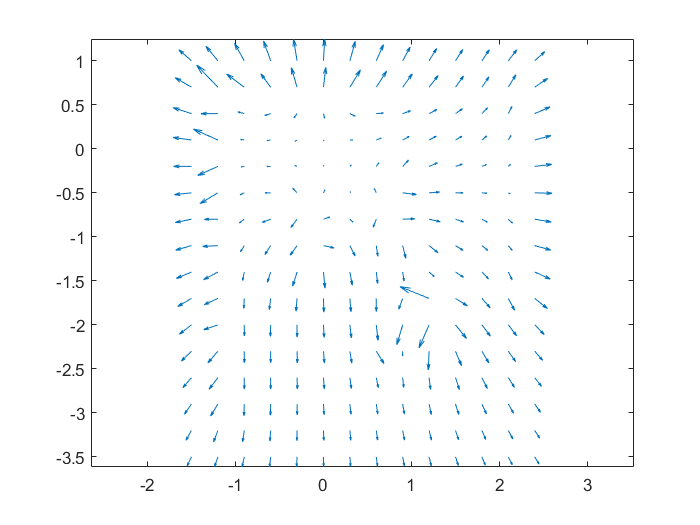

% Quiver Plot

syms x y
bob_radius = 0.25;

positions = load('all_positions.mat').all_positions;
headings  = load('all_headings.mat').all_headings;

all_points = [];

for i=1:2
    scan = load(['scan' num2str(i) '.mat']);
    
    p = positions(i, :);
    h = headings(i, :);
    
    orient = atan2(h(2), h(1));
    points = convertLidarToGlobal(scan.r, scan.theta, p, orient);
    
    all_points = [all_points ; points];
end

[line_inliers, circle_inliers, circle_center] = detectObjects(all_points, bob_radius);
p_field = create_potential_field(line_inliers, circle_inliers);
grad    = gradient(p_field, [x y]);

[xs, ys] = meshgrid(-1.5:0.3:2.5, -3.5:0.3:1);
v = double(subs(grad, {x, y}, {xs, ys}));
half = floor(length(v) / 2);

quiver(xs, ys, v(1:half, :), v(half+1:end, :))
axis equal

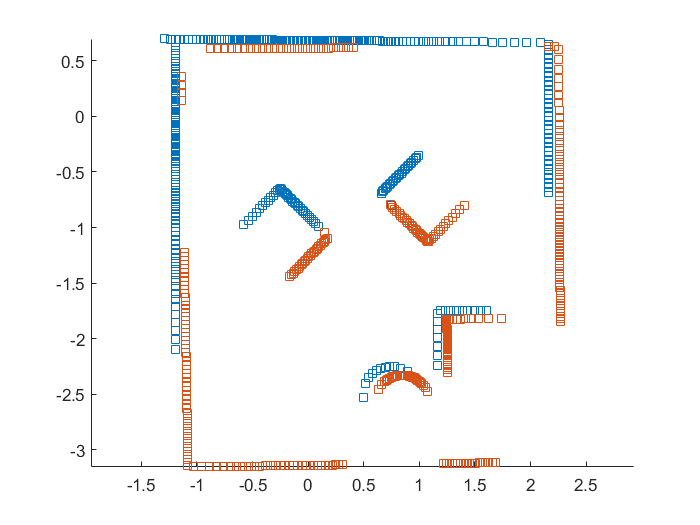

% Gauntlet map
% todo: added fitted lines

bob_radius = 0.25;

positions = load('all_positions.mat').all_positions;
headings  = load('all_headings.mat').all_headings;

all_points = [];

figure
hold on

for i=1:2
    scan = load(['scan' num2str(i) '.mat']);
    
    p = positions(i, :);
    h = headings(i, :);
    
    orient = atan2(h(2), h(1));
    points = convertLidarToGlobal(scan.r, scan.theta, p, orient);
    
    plot(points(:, 1), points(:, 2), 's')
end

axis equal
hold off

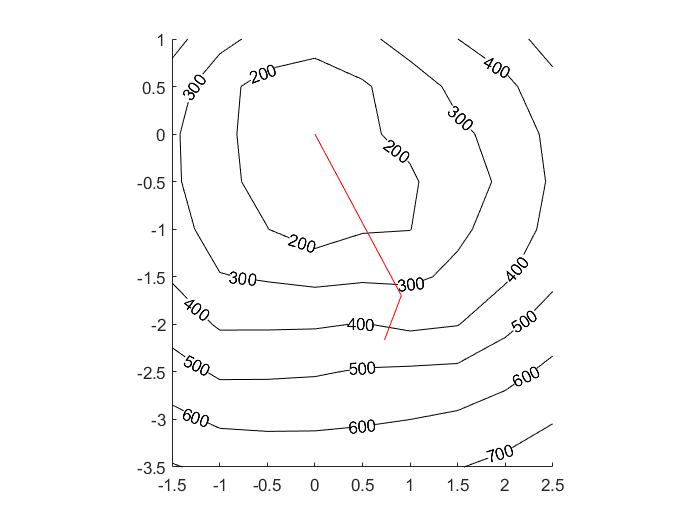

% Gradient descent
% todo: last position in positions matrix too far... need to manually
% shorten it (neato kept driving after touching bob)

syms x y
bob_radius = 0.25;

positions = load('all_positions.mat').all_positions;
headings  = load('all_headings.mat').all_headings;

v1 = positions(2, :);
v2 = positions(3, :);
positions(3, :) = v1 + ((v2 - v1) / (2*norm(v2 - v1)));

all_points = [];

for i=1:2
    scan = load(['scan' num2str(i) '.mat']);
    
    p = positions(i, :);
    h = headings(i, :);
    
    orient = atan2(h(2), h(1));
    points = convertLidarToGlobal(scan.r, scan.theta, p, orient);
    
    all_points = [all_points ; points];
end

[line_inliers, circle_inliers, circle_center] = detectObjects(all_points, bob_radius);
p_field = create_potential_field(line_inliers, circle_inliers);

figure
hold on

[xs, ys] = meshgrid(-1.5:0.5:2.5, -3.5:0.5:1);
v = double(subs(p_field, {x, y}, {xs, ys}));
contour(xs, ys, v, 'k', 'ShowText', 'On')

plot(positions(:, 1), positions(:, 2), 'r-')

axis equal
hold off

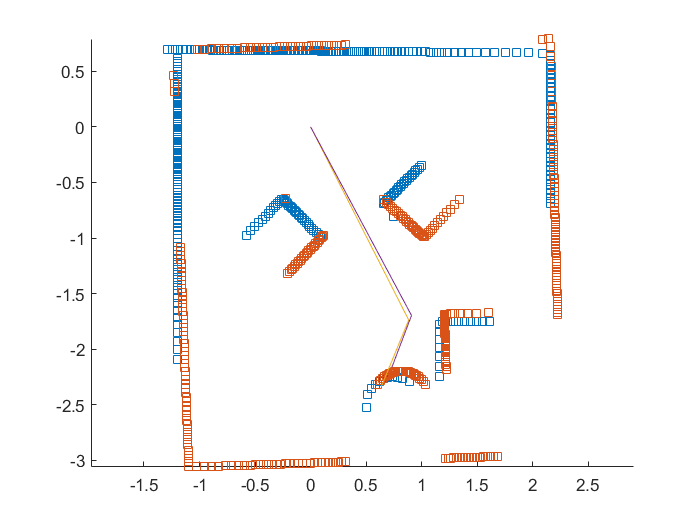

% Experimental validation

bob_radius = 0.25;

positions = load('all_positions.mat').all_positions;
headings  = load('all_headings.mat').all_headings;

v1 = positions(2, :);
v2 = positions(3, :);
positions(3, :) = v1 + ((v2 - v1) / (2*norm(v2 - v1)));

all_points = [];

figure
hold on

for i=1:2
    scan = load(['scan' num2str(i) '.mat']);
    
    p = positions(i, :);
    h = headings(i, :);
    
    orient = atan2(h(2), h(1));
    points = convertLidarToGlobal(scan.r, scan.theta, p, orient);
    
    plot(points(:, 1), points(:, 2), 's')
end

enc = readmatrix('encoder_data.csv');
enc = enc(1:455, :);
left  = diff(enc(:, 2)) ./ diff(enc(:, 1));
right = diff(enc(:, 3)) ./ diff(enc(:, 1));
l_vel = (left + right) / 2;
a_vel = (right - left) / 0.235;
t = diff(enc(:, 1));%cumsum(diff(enc(:, 1)));

thetas = cumsum(a_vel .* t);
x = cumsum(l_vel .* cos(thetas) .* t);
y = cumsum(l_vel .* sin(thetas) .* t);
plot(x, y)

plot(positions(:, 1), positions(:, 2))

axis equal
hold off